# Example:

Consider a rectangular piece of $120\times 160 \,\text{mm}$ and thickness $t_{h} = 0.0036\,\text{mm}$. Its left side is fixed to the wall, whereas its right side is pulled by a constant traction $\tau_{0} = 1000\,\text{N/mm}$ (see Figure 1).

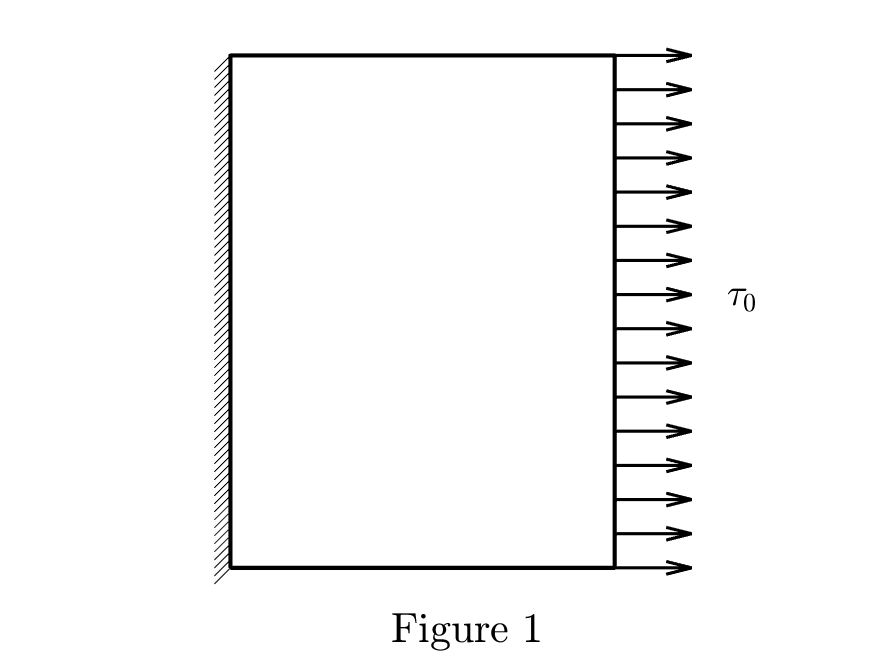

Using the mesh in Figure 2, compute the **displacements **if the material has $E = 30\times 10^{6}\,\text{N/mm}^{2}$ and $\nu = 0.25$.

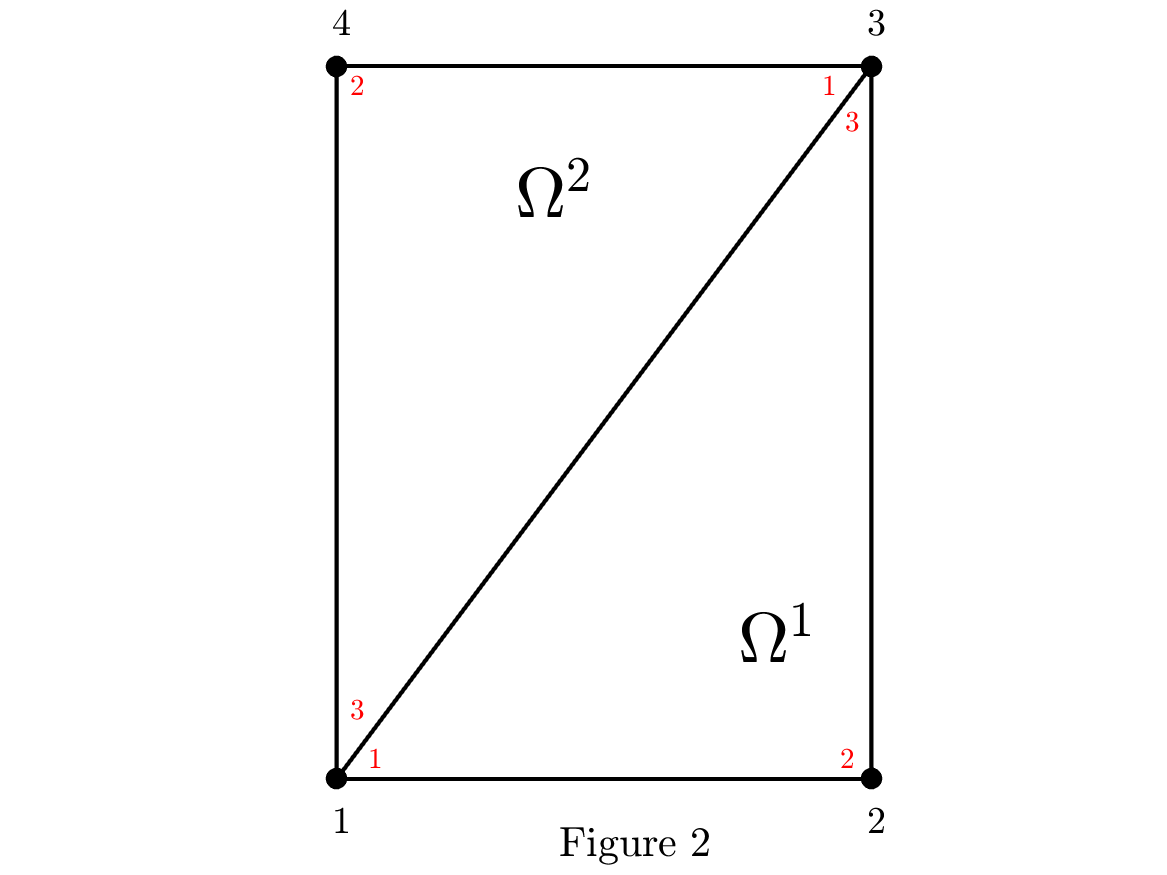

### **Solution**

If we place the origin of coordinates at (global) node $1$,  and the horizontal and vertical axes on the edges joining the global nodes $1$ and $2$, and $1$ and $4$, respectively, the matrix with the position of the nodes is 

            
$$\texttt{nodes} = \left(\begin{array}{rr} 0 & 0\\ 120 & 0 \\ 120 & 160 \\ 0 & 160\end{array}\right)$$
 

    and, according to the mesh shown in Figure 2, the connectivity matrix is 

            $\texttt{elem} = \left(\begin{array}{ccc} 1 & 2 & 3 \\ 3 & 4 & 1\end{array}\right)$. 

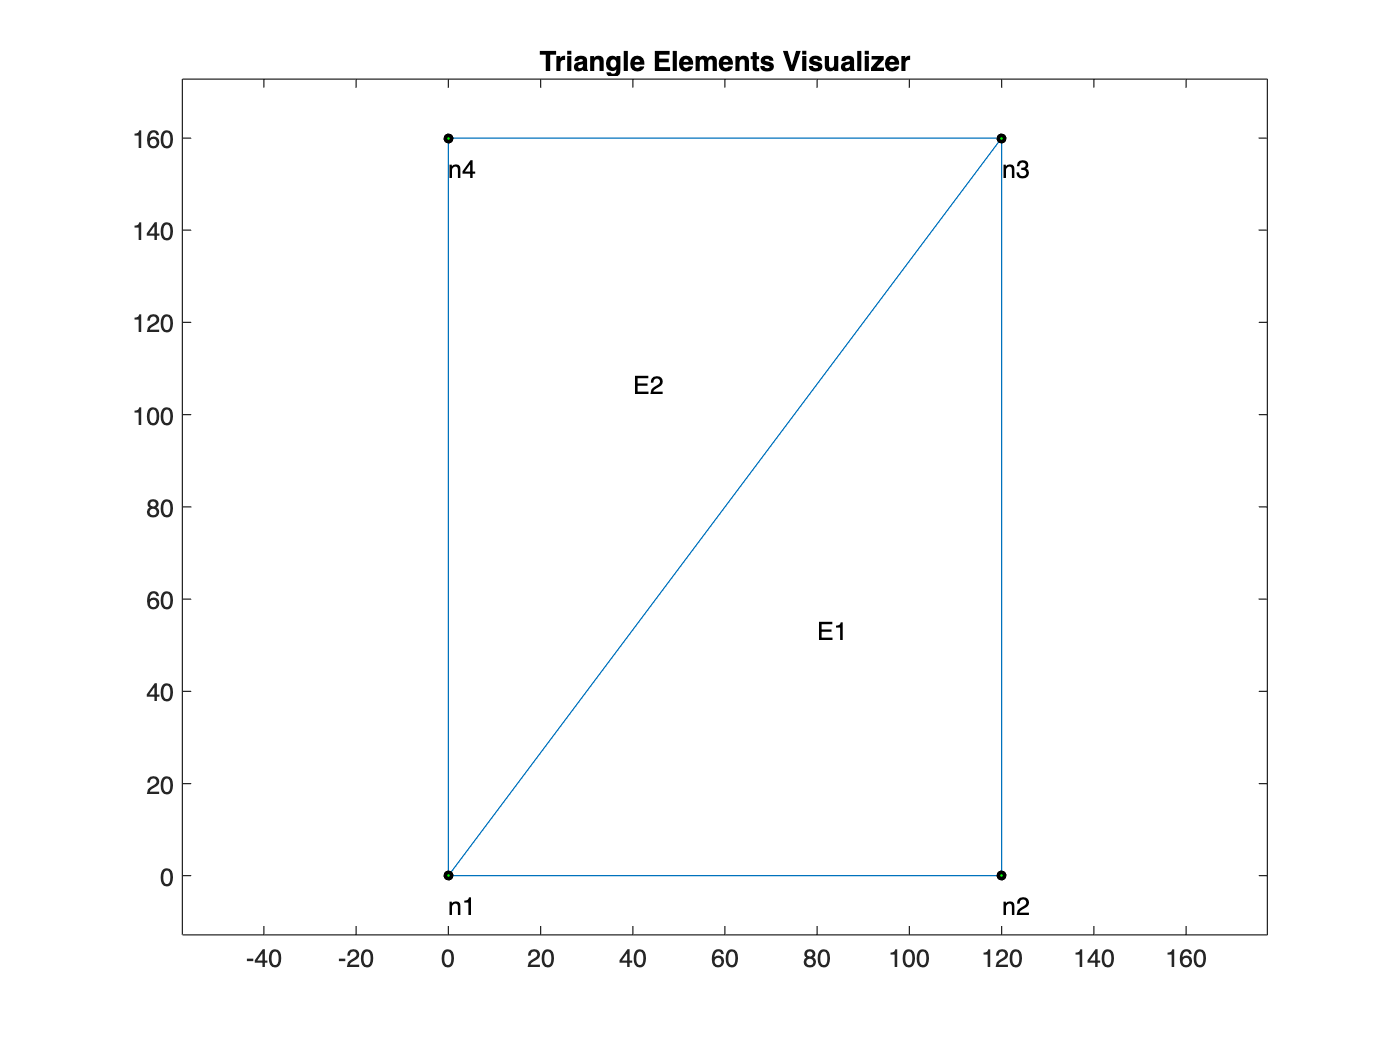

clearvars
close all

excelFileDispl='displacements.xlsx'; 
excelFileStressElements = 'stressElements.xlsx';
excelFileStressNodes = 'stressNodes.xlsx';

th =0.036;     %mm
tau0 = 1000.0; %N/mm;
E = 3.0e7;     %N/mm^2 
nu = 0.25;

nodes = [0,0;
    120, 0;
    120,160;
    0,160];  

elem = [1,2,3;
    3,4,1];

numNodes = size(nodes,1);
numElem = size(elem,1);
dim = size(nodes,2);

numbering = 1;
plotElementsOld(nodes, elem, numbering)

#### Local stiffness matrix of element $\Omega^{1}$, $K^{1}$:   

First, compute matrix $B^{1}$: 

            
$$ B^{1}=\left(\begin{array}{c|c|c} B^{1}_{1} & B^{1}_{2} & B^{1}_{3}\end{array}\right) = \frac{1}{2A_{1}}\left(\begin{array}{cc|cc|cc}
                      \beta^{1}_{1} & 0 & \beta^{1}_{2} & 0 & \beta^{1}_{3} & 0\\
                     0 & \gamma^{1}_{1} & 0 & \gamma^{1}_{2} & 0 & \gamma^{1}_{3}\\
                     \gamma^{1}_{1} & \beta^{1}_{1} & \gamma^{1}_{2} & \beta^{1}_{2} & \gamma^{1}_{3} & \beta^{1}_{3}
                \end{array}\right) =
\frac{1}{480}\left(\begin{array}{rr|rr|rr}
    -4 & 0 & 4 & 0 & 0 & 0\\
    0 & 0 & 0 & -3 & 0 & 3\\
   0 & -4 & -3 & 4 & 3 & 0\end{array}\right),$$


where:

- $A_{1}$is the area of the element, $A_{1} = \frac{120\times 160}{2} = 9600 \,\text{mm}^{2}$.

- $\beta^{1}_{i} = y^{1}_{j} - y^{1}_{k}$, $(i,j,k) = (1,2,3)$, plus cyclic permutations, so: $\left\{\begin{array}{l} \beta^{1}_{1} = y^{1}_{2} - y^{1}_{3} = 0 - 160 = -160,\\ \beta^{1}_{2} = y^{1}_{3} - y^{1}_{1} = 160 - 0 = 160,\\ \beta^{1}_{3} = y^{1}_{1} - y^{1}_{2} = 0 - 0 = 0.\end{array}\right.$

- $\gamma^{1}_{i} = -(x^{1}_{j}-x^{1}_{k})$, $(i,j,k)=(1,2,3)$, plus cyclic permutations, so: $\left\{\begin{array}{l} \gamma^{1}_{1} = -(x^{1}_{2} - x^{1}_{3}) = -(120 - 120) = 0,\\ \gamma^{1}_{2} = -(x^{1}_{3} - x^{1}_{1}) = -(120 - 0) = -120,\\ \gamma^{1}_{3} = -(x^{1}_{1} - x^{1}_{2}) = -(0-120) = 120.\end{array}\right.$

- The blocks $B^{1}_{i}$, $i=1,2,3$ are given by, $B^{1}_{i} = \frac{1}{2A_{i}}\left(\begin{array}{cc} \beta^{1}_{i} & 0\\ 0 & \gamma^{1}_{i} \\ \gamma^{1}_{i} & \beta^{1}_{i}\end{array}\right)$, $i=1,2,3$

Next, we need the components of the matrix $C = \left(\begin{array}{cc|c} c_{11} & c_{12} & \\ c_{21} & c_{22} & \\ \hline & & c_{33}\end{array}\right)$. As this problem is a *stress *problem, the coefficiens of the matrix are given by,

            
$$\begin{array}{l}
c_{11} = c_{22} = \frac{E}{1-\nu^{2}} = \frac{3\times 10^{7}}{1-0.25^{2}}=\frac{16}{5}\times 10^{7} = 3.2\times 10^{7},\\
c_{12}=c_{21} = \nu c_{11} = 0.8\times 10^{7},\\
c_{33} = \frac{E}{2(1+\nu)} = \frac{3.0\times 10^{7}}{2(1+0.25)} = \frac{6}{5}\times 10^{7} = 1.2\times 10^{7},
\end{array}$$


so $C = \left(\begin{array}{cc|c} c_{11} & c_{12} & \\ c_{21} & c_{22} & \\ \hline & & c_{33}\end{array}\right) = 4\times 10^6\, \left(\begin{array}{cc|c} 8 & 2 & \\ 2 & 8 & \\  \hline & & 3\end{array}\right)$, and then $K^{1} = t_{h} A_{1} \left(B^{1}\right)^{\top} C B^{1} = \left(\begin{array}{c|c|c} K_{11} & K_{12} & K_{13} \\ \hline K_{21} & K_{22} & K_{23} \\ \hline K_{31} & K_{32} & K_{33}\end{array}\right)$, where $K_{ij}$, $i,j = 1,2,3$are $2\times 2$ blocs given by $K_{ij} = t_{h} A_{1} \left(B^{1}_{i}\right)^{\top} C B^{1}_{j}$, $i,j = 1,2,3$. Hence the stiffness matrix of element $\Omega^{1}$ is 


$$K^{1} = t_{h} A_{1} \left(B^{1}\right)^{\top} C B^{1} = t_{h} A_{1}\left(\begin{array}{c|c|c}
\left(B^{1}_{1}\right)^{\top} C B^{1}_{1} & \left(B^{1}_{1}\right)^{\top} C B^{1}_{2} & \left(B^{1}_{1}\right)^{\top} C B^{1}_{3} \\ \hline
\left(B^{1}_{2}\right)^{\top} C B^{1}_{1} & \left(B^{1}_{2}\right)^{\top} C B^{1}_{2} & \left(B^{1}_{2}\right)^{\top} C B^{1}_{3} \\ \hline
\left(B^{1}_{3}\right)^{\top} C B^{1}_{1} & \left(B^{1}_{3}\right)^{\top} C B^{1}_{2} & \left(B^{1}_{3}\right)^{\top} C B^{1}_{3} \end{array}\right) \\
\quad = 6\times 10^{3}\,\left(\begin{array}{rrr} -4 & 0 & 0 \\
0 & 0 & -4\\ \hline
4 & 0 & -3 \\ 
0 & -3 & 4 \\ \hline
0 & 0 & 3\\
0 & 3 & 0\end{array}\right)\,
 \left(\begin{array}{cc|c} 8 & 2 & \\ 2 & 8 & \\  \hline & & 3\end{array}\right)\,
\left(\begin{array}{rr|rr|rr}
-4 & 0 & 4 & 0 & 0 & 0 \\ 
0 & 0 & 0 & -3 & 0 & 3 \\
0 & -4 & -3 & 4 & 3 & 0\end{array}\right)= 
6\times 10^{3}\, \left(\begin{array}{rr|rr|rr}
128 & 0 & -128 & 24 & 0 & -24\\
0 & 48 & 36 & -48 & -36 & 0\\ \hline
-128 & 36 & 155 & -60 & -27 & 24\\
24 & -48 & -60 & 120 & 36 & -72\\ \hline
0 & -36 & -27 & 36 & 27 & 0\\
-24 & 0 & 24 & -72 & 0 &  72\end{array}\right).$$


#### Local stiffness matrix of element $\Omega^{2}$, $K^{2}$:

*Exercise:* check that, in this case, $\beta^{2}_{i} = -\beta^{1}_{i}$ and $\gamma^{2}_{i} = -\gamma^{1}_{i}$, $i=1,2,3$ (Exercise: check it!). Therefore $B^{2} = -B^{1}$, and hence $K^{2} = K^{1}$.

#### Assembly

We can use the usual assembling rules and get the global stiffness matrix whether from the connectivity matrix or directly from the node connections shown in Figure 2. *Remark. *Here, instead of summing up the coefficients of the local stiffness matrices, we must sum up the $2\times 2$ blocs.

        $K = \left(\begin{array}{c|c|c|c} 
K^{1}_{11} + K^{2}_{33} & K^{1}_{12} & K^{1}_{13} + K^{2}_{31} & K^{2}_{32}\\ \hline
K^{1}_{21} & K^{1}_{22} & K^{1}_{23} & 0\\ \hline
K^{1}_{31} + K^{2}_{13} & K^{1}_{32} & K^{1}_{33} + K^{2}_{11} & K^{2}_{12} \\ \hline
K^{2}_{23} & 0 & K^{2}_{21} & K^{2}_{22}\end{array}\right) =
6\times 10^{3}\, \left(\begin{array}{rr|rr|rr|rr}
155 & 0 & -128 & 24 & 0 & -60 & -27 & 36\\
0 & 120 & 36 & -48 & -60 & 0 & 24 & -72 \\ \hline
-128 & 36 & 155 & -60 & -27 & 24 & 0 & 0\\
24 & -48 & -60 & 120 & 36 & -72 & 0 & 0 \\ \hline
0 & -60 & -27 & 36 & 155 & 0 & -128 & 24\\
-60 & 0 & 24 & -72 & 0 & 120 & 36 & -48 \\ \hline
-27 & 24 & 0 & 0 & -128 & 36 & 155 & -60 \\
36 & -72 & 0 & 0 & 24 & -48 & -60 & 120\end{array}\right)$.

Therefore, the assembled system is

        $6\times 10^{3}\, \left(\begin{array}{rr|rr|rr|rr}
155 & 0 & -128 & 24 & 0 & -60 & -27 & 36\\
0 & 120 & 36 & -48 & -60 & 0 & 24 & -72 \\ \hline
-128 & 36 & 155 & -60 & -27 & 24 & 0 & 0\\
24 & -48 & -60 & 120 & 36 & -72 & 0 & 0 \\ \hline
0 & -60 & -27 & 36 & 155 & 0 & -128 & 24\\
-60 & 0 & 24 & -72 & 0 & 120 & 36 & -48 \\ \hline
-27 & 24 & 0 & 0 & -128 & 36 & 155 & -60 \\
36 & -72 & 0 & 0 & 24 & -48 & -60 & 120\end{array}\right)\, \left(\begin{array}{c}
U_{1} \\ V_{1} \\ \hline U_{2} \\ V_{2} \\ \hline U_{3} \\ V_{3} \\ \hline U_{4} \\ V_{4}\end{array}\right) = \left(\begin{array}{c} Q_{1x}\\ Q_{1y} \\ \hline Q_{2x} \\ Q_{2y} \\ \hline Q_{3x} \\ Q_{3y} \\ \hline Q_{4x} \\ Q_{4y}\end{array}\right) + \left(\begin{array}{c} F_{1x}\\ F_{1y} \\ \hline F_{2x} \\ F_{2y} \\ \hline F_{3x} \\ F_{3y} \\ \hline F_{4x} \\ F_{4y}\end{array}\right) $.

Note that in this case the body forces $F=\left(\begin{array}{cc|cc|cc|cc} F_{1x} & F_{1y} & F_{2x} & F_{2y} & F_{3x} & F_{3y} & F_{4x} & F_{4y}\end{array}\right)^{\top} = 0$, for no internal forces (for example, the weight) are considered.

K = zeros(dim*numNodes);
Q = zeros(dim*numNodes,1);
F = zeros(dim*numNodes,1);
B = cell(numElem,1);

C = zeros(3,3);

%Coefficients for stress problems  
C(1,1)= E/(1-nu^2);
C(1,2)= nu*C(1,1);
C(2,1)= C(1,2);
C(2,2)= C(1,1);
C(3,3)= 0.5*E/(1+nu);

for e=1:numElem 
    [Ke,B{e}] = planeElastTriangStiffMatrixJR(nodes,elem,C,th,e); %Compute the local stiffness matrix
    rows = [dim*elem(e,1)-1, dim*elem(e,1), ...
        dim*elem(e,2)-1, dim*elem(e,2),...
        dim*elem(e,3)-1, dim*elem(e,3)];
    cols = rows;
    K(rows,cols) = K(rows,cols) + Ke; %Assembly
end

#### Natural B.C.

$Q_{2} = Q^{1}_{21} + Q^{1}_{22} + Q^{1}_{23} = Q^{1}_{22}$, $Q_{3} = Q^{1}_{31} + Q^{1}_{32} + Q^{1}_{33} + Q^{2}_{11} + Q^{2}_{12} + Q^{2}_{13} = Q^{1}_{32}$, $Q^{1}_{31} = 0$, $Q^{2}_{11} = 0$, $Q^{2}_{12} =0$, $Q^{1}_{33} + Q^{2}_{13} = 0$.

         $Q_{2} = Q^{1}_{22} = \displaystyle \int_{0}^{h^{1}_{2}} \left(\begin{array}{cc} \psi^{1}_{22}(s) & 0 \\ 0 & \psi^{1}_{22}(s)\end{array}\right) \biggl(\begin{array}{c} \tau_{0}\\ 0\end{array}\biggr)\mathrm{d} s = \frac{\tau_{0}}{h^{1}_{2}} \int_{0}^{h^{1}_{2}} \left(\begin{array}{cc} h^{1}_{2} - s & 0\\ 0 & h^{1}_{2} - s\end{array}\right) \left(\begin{array}{c} 1\\ 0\end{array}\right)\mathrm{d} s = h^{1}_{2}\frac{\tau_{0}}{2}\left(\begin{array}{c} 1 \\ 0\end{array}\right) = 160\times\frac{1000}{2}\left(\begin{array}{c} 1\\ 0\end{array}\right) = 8\times 10^{4}\,\left(\begin{array}{c} 1\\ 0\end{array}\right)$,

        $Q_{3} = Q^{1}_{32} = \displaystyle \int_{0}^{h^{1}_{2}} \left(\begin{array}{cc} \psi^{1}_{32}(s) & 0 \\ 0 & \psi^{1}_{32}(s)\end{array}\right) \biggl(\begin{array}{c} \tau_{0}\\ 0\end{array}\biggr)\mathrm{d} s = \frac{\tau_{0}}{h^{1}_{2}} \int_{0}^{h^{1}_{2}}\left(\begin{array}{cc} s & 0\\ 0 & s\end{array}\right) \left(\begin{array}{c} 1\\ 0\end{array}\right)\mathrm{d} s = h^{1}_{2}\frac{\tau_{0}}{2}\left(\begin{array}{c} 1 \\ 0\end{array}\right) = 8\times 10^{4}\,\left(\begin{array}{c} 1\\ 0\end{array}\right)$.

**Remark. **As the traction, $\tau_{0}$ is given in $\text{N/mm}$(force units / length units), we compute the $Q$'s without multiplying by thickness, $t_{h}$. Nevertheless, in the computations of the stifness matrix and the body forces (the $F$'s), we** must **multyply by $t_{h}$for the formulas to have the correct dimensions. For now on, this will be our general criteria.

fixedNods = [];
nod=1;
fixedNods = [fixedNods,dim*nod-1,dim*nod];
nod=4;
fixedNods = [fixedNods,dim*nod-1,dim*nod];

freeNods = setdiff(1:dim*numNodes,fixedNods);

%Natural B.C.: 

%Remark. As the traction, tau0, is given in N/mm 
% (force units/length units, we compute the Q's
% without multiplying by the thickness, th

%On side 2 of element 1 (local nodes 2 and 3)
h = norm(nodes(elem(1,2),:)-nodes(elem(1,3),:));

nod=2; %global node (node 2 of element 1)
Q(dim*nod-1) = h*tau0/2;    % Q2x = h*tau0/2 
Q(dim*nod) = 0.0;           % Q2y = 0;

nod=3; %global node (node 3 of element 1)
Q(dim*nod-1) = h*tau0/2;    % Q3x = h*tau0/2
Q(dim*nod) = 0.0;           % Q3y = 0;

#### Essential Boundary conditions

The left edge is fixed, so $U_{1} =  u^{1}_{1} = u^{2}_{3} = 0$, $V_{1} = v_{1}^{1} = v^{2}_{3} = 0$, $U_{4} = u^{2}_{2} = 0$, $V_{4} = v^{2}_{2} = 0$.

%Essential B.C.
u = zeros(dim*numNodes,1);
u(fixedNods,1) = 0;

#### Reduced system

        $\left(\begin{array}{rr|rr} 
155 & -60& -27 & 24\\
-60 & 120 & 36 & -72 \\ \hline
-27 & 36 & 155 & 0 \\
24 & -72 & 0 & 120\end{array}\right)\,\left(\begin{array}{c}
U_{2} \\ 
V_{2} \\ \hline
U_{3} \\
V_{3}\end{array}\right) = 
\left(\begin{array}{c} 
 40/3\\ 
0\\ \hline
40/3 \\
0\end{array}\right)$.  Solution: $\left\{\begin{array}{l} U_{2} = u^{1}_{2} = 1.1291\times 10^{-1}\,\text{mm},\\ V_{2} = v^{1}_{2} = 1.9637\times 10^{-2}\,\text{mm},\\ U_{3} = u^{1}_{3} = u^{2}_{1} = 1.0113\times 10^{-1}\,\text{mm},\\ V_{3} = v^{1}_{3} = v^{2}_{1} = -1.0800\times 10^{-2}\,\text{mm}.\end{array}\right.$

%Reduced system
Km = K(freeNods,freeNods);
Qm = Q(freeNods) - K(freeNods,fixedNods)*u(fixedNods,1);

%Solve the reduced system
um = Km\Qm;
u(freeNods,1)= um;

% Displacements
format short e
displTable=table((1:numNodes)',nodes(:,1),nodes(:,2),...
                  u(1:2:end),u(2:2:end),...
                  'VariableNames',{'Nod','X','Y','UX','UY'});

%Write table to an Excel file                      
writetable(displTable,excelFileDispl);
%And show the displacements just for the last 10 nodes
displTable

displTable = 4×5 table
       Nod            X             Y             UX            UY     
    __________    __________    __________    __________    ___________

    1.0000e+00    0.0000e+00    0.0000e+00    0.0000e+00     0.0000e+00
    2.0000e+00    1.2000e+02    0.0000e+00    1.1291e-01     1.9637e-02
    3.0000e+00    1.2000e+02    1.6000e+02    1.0113e-01    -1.0800e-02
    4.0000e+00    0.0000e+00    1.6000e+02    0.0000e+00     0.0000e+00


#### Post process. Stress

Since we use linear triangular elements, the stress tensor is constant over all the element. and is given by $\sigma^{e} = CB^{e} u^{e}$, with

         $\sigma^{e} = \left(\begin{array}{ccc} \sigma^{e}_{x} & \sigma^{e}_{y} & \sigma^{e}_{xy}\end{array}\right)^{\top}$, $u^{e} = \left(\begin{array}{cc|cc|cc} u^{e}_{1} & v^{e}_{1} & u^{e}_{2} & v^{e}_{2} & u^{e}_{3} & v^{e}_{3}\end{array}\right)^{\top}$, $e = 1,2$.

- For $\Omega^{1}$: $\left(\begin{array}{c} \sigma^{1}_{x} \\ \sigma^{1}_{y} \\ \tau^{1}_{xy}\end{array}\right) = \frac{10^{5}}{12}\,\left(\begin{array}{cc|c} 8 & 2 & \\ 2 & 8 & \\  \hline & & 3\end{array}\right)\,\left(\begin{array}{rr|rr|rr} -4 & 0 & 4 & 0 & 0 & 0\\ 0 & 0 & 0 & -3 & 0 & 3\\ 0 & -4 & -3 & 4 & 3 & 0\end{array}\right)\, \left(\begin{array}{c} \begin{array}{c} 0 \\ 0\end{array}\\ \hline \begin{array}{r} 1.1291 \times 10^{-1} \\ 1.9637\times 10^{-2}\end{array} \\ \hline \begin{array}{r} 1.0113\times 10^{-1}\\ -1.0800\times 10^{-2}\end{array}\end{array}\right) = \left(\begin{array}{r} 2.8588\times 10^{4}\\ 1.4400\times 10^{3}\\ 1.0800\times 10^{3}\end{array}\right),\, \text{  in N/mm}^{2}$.

- For $\Omega^{2}$: $\left(\begin{array}{c} \sigma^{2}_{x} \\ \sigma^{2}_{y} \\ \tau^{2}_{xy}\end{array}\right) = \frac{10^{5}}{12}\,\left(\begin{array}{cc|c} 8 & 2 & \\ 2 & 8 & \\  \hline & & 3\end{array}\right)\,\left(\begin{array}{rr|rr|rr} 4 & 0 & -4 & 0 & 0 & 0\\ 0 & 0 & 0 & 3 & 0 & -3\\ 0 & 4 & 3 & -4 & -3 & 0\end{array}\right)\, \left(\begin{array}{c} \begin{array}{r} 1.0113\times 10^{-1} \\  -1.0800\times 10^{-2}\end{array}\\ \hline \begin{array}{c} 0 \\ 0\end{array} \\ \hline \begin{array}{r} 0\\ 0\end{array}\end{array}\right) = \left(\begin{array}{r} 2.6968\times 10^{4}\\ 6.7419\times 10^{3}\\ -1.0800\times 10^{3}\end{array}\right),\, \text{  in N/mm}^{2}$.

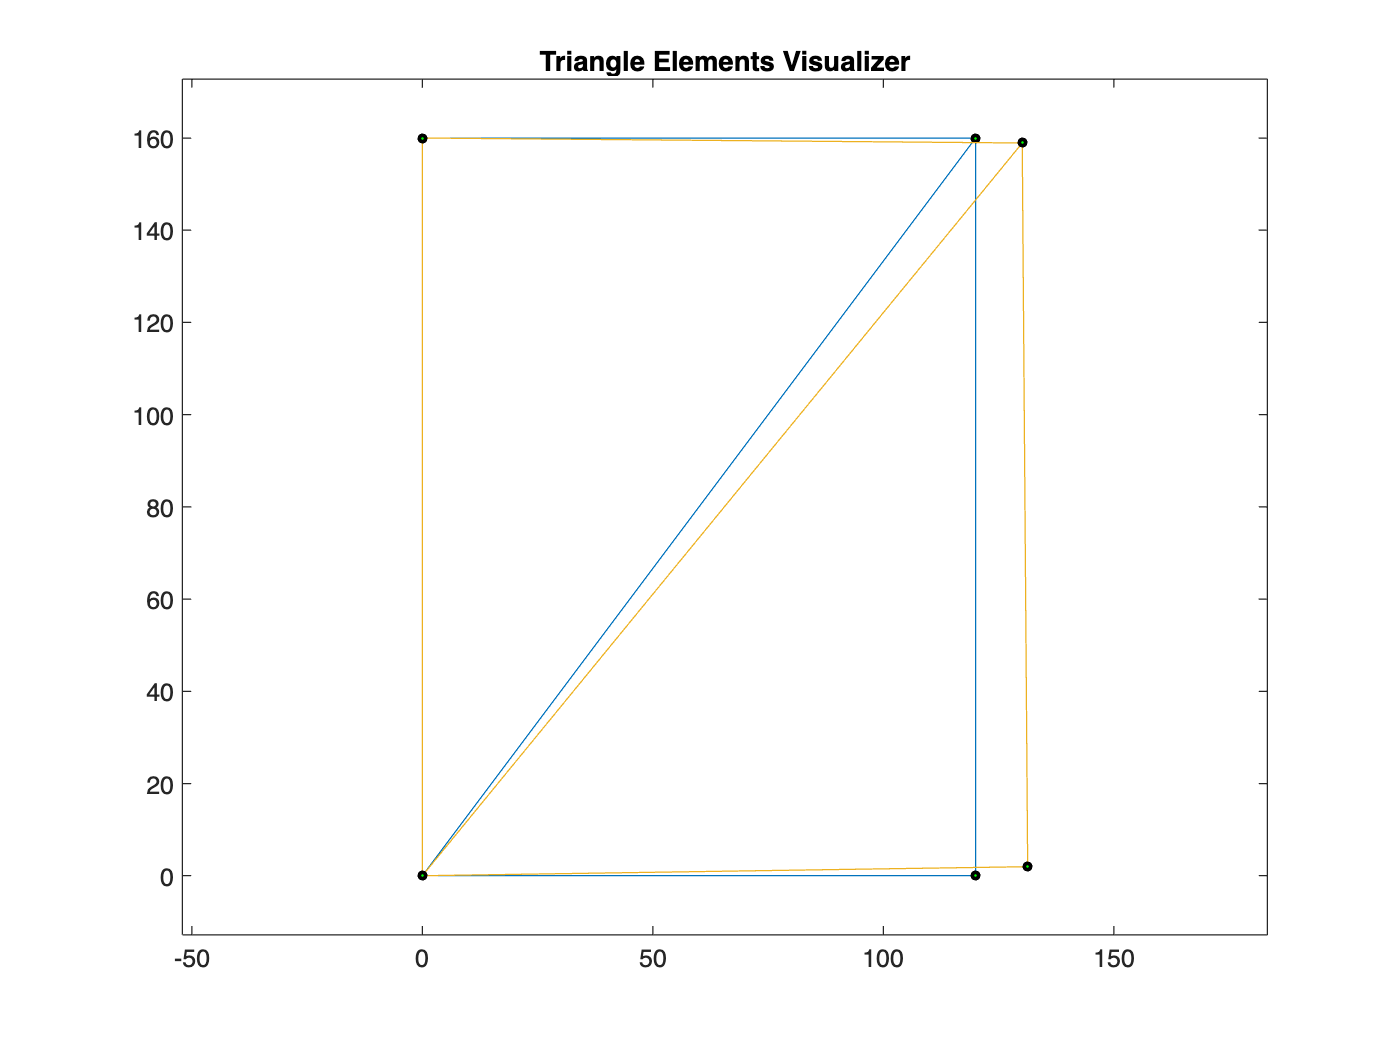

%Post Process

%Plot the displacements
scale=1.0e2;
plotPlaneNodElemDespl(nodes, elem, u, scale);


%Contour plot for the x-displacements
ux = u(1:2:end);
colorScale = 'jet';
title = 'x-displacements';

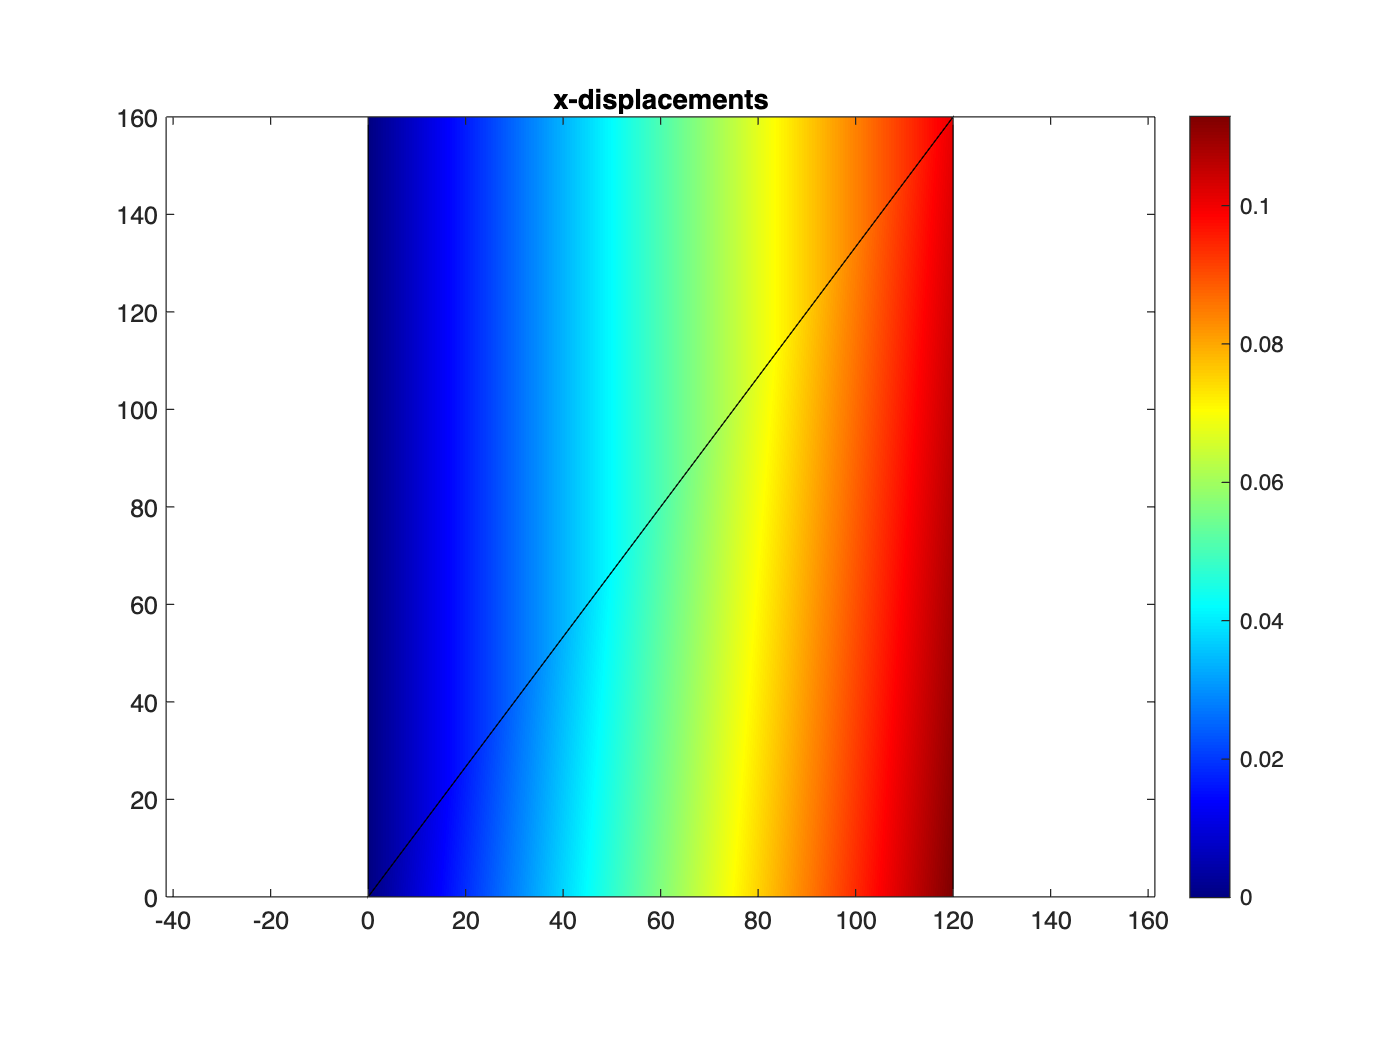

plotContourSolution(nodes,elem,ux,title,colorScale);

Components if the stress tensor: $\sigma_{x}$, $\sigma_{y}$, and $\tau_{xy}$ at elements

%sigma-X, sigma-Y, tau-XY at nodes
sigma = zeros(3,numElem);

for e = 1:numElem
    rows = [dim*elem(e,1)-1, dim*elem(e,1), dim*elem(e,2)-1, dim*elem(e,2),...
        dim*elem(e,3)-1, dim*elem(e,3)];
    sigma(:,e) = C*B{e}*u(rows);    
end
sigma = sigma';

%Sigma-VM at the nodes
vonMises = sqrt(sigma(:,1).^2 + sigma(:,2).^2 ...
    - sigma(:,1).*sigma(:,2) + 3*sigma(:,3).^2);

% Table with the stress tensor SX, SY, SXY
stressElemTable=table((1:numElem)',sigma(:,1),sigma(:,2),sigma(:,3),vonMises,...
                  'VariableNames',{'Elem','Sigma-X','Sigma-Y','Tau-XY','Sigma-VM'});
%Write table to an Excel file                      
writetable(stressElemTable,excelFileStressElements);                            
stressElemTable

stressElemTable = 2×5 table
       Elem        Sigma-X       Sigma-Y        Tau-XY        Sigma-VM 
    __________    __________    __________    ___________    __________

    1.0000e+00    2.8588e+04    1.4400e+03     1.0800e+03    2.7958e+04
    2.0000e+00    2.6968e+04    6.7419e+03    -1.0800e+03    2.4380e+04


Components if the stress tensor: $\sigma_{x}$, $\sigma_{y}$, and $\tau_{xy}$ at nodes

%Stress and VM stress for the nodes (taken form the original code in 
%computeQuadStrainStressVM.m, available at professor Toni Susin's Numerical 
%Factory)

%sigma-X, sigma-Y, tau-XY at nodes
sigmaNod = zeros(numNodes,3);

for e=1:numElem
    sigmaNod(elem(e,:),:) = sigmaNod(elem(e,:),:) + sigma(e,:);
end

nodInElem=zeros(numNodes,1);
for i=1:numNodes
    elements=elemContainNod(i,elem);
    nodInElem(i)=size(elements,2); %how many elements the node ith belongs
end

sigmaNod=sigmaNod./nodInElem;

%Sigma-VM at nodes 
vonMisesNod = sqrt(sigmaNod(:,1).^2 + sigmaNod(:,2).^2 ...
    - sigmaNod(:,1).*sigmaNod(:,2)+ 3*sigmaNod(:,3).^2);

% Table with the stress tensor components at each point
stressNodesTable=table((1:numNodes)',sigmaNod(:,1),sigmaNod(:,2),sigmaNod(:,3),vonMisesNod,...
                  'VariableNames',{'Node','Sigma-X','Sigma-Y','Tau-XY','Sigma-VM'});
%Write table to an Excel file                      
writetable(stressNodesTable,excelFileStressNodes);                            
stressNodesTable

stressNodesTable = 4×5 table
       Node        Sigma-X       Sigma-Y        Tau-XY        Sigma-VM 
    __________    __________    __________    ___________    __________

    1.0000e+00    2.7778e+04    4.0910e+03     5.6843e-13    2.5975e+04
    2.0000e+00    2.8588e+04    1.4400e+03     1.0800e+03    2.7958e+04
    3.0000e+00    2.7778e+04    4.0910e+03     5.6843e-13    2.5975e+04
    4.0000e+00    2.6968e+04    6.7419e+03    -1.0800e+03    2.4380e+04
